% 设置中文字体
set(groot, 'DefaultAxesFontName', 'Kaiti');
set(groot, 'DefaultTextFontName', 'Kaiti');

fprintf('============================================================\n');

fprintf('案例2：社交媒体用户增长预测\n');

案例2：社交媒体用户增长预测


fprintf('基于Logistic增长模型的非线性回归分析\n');

基于Logistic增长模型的非线性回归分析


fprintf('============================================================\n');

%% 1. 数据生成 - 模拟真实社交媒体用户增长
function [months, observed_users, true_users, base_users, true_params] = generate_social_media_data(n_months, noise_level)
    if nargin < 1
        n_months = 18;
    end
    if nargin < 2
        noise_level = 0.08;
    end
    
    rng(123);  % 设置随机种子
    
    % 时间序列（月份）
    months = 1:n_months;
    
    % 真实的Logistic增长参数
    L = 1000000;    % 最大用户数（100万）
    k = 0.6;        % 增长率
    x0 = 8;         % 拐点时间（第8个月）
    true_params = [L, k, x0];
    
    % 基础Logistic增长
    base_users = L ./ (1 + exp(-k * (months - x0)));
    
    % 添加季节性变化（模拟节假日效应）
    seasonal_factor = 1 + 0.1 * sin(2 * pi * months / 12);
    
    % 添加营销活动影响（在第4、9、14个月）
    marketing_boost = zeros(size(months));
    marketing_months = [4, 9, 14];
    for month = marketing_months
        if month <= length(months)
            % 营销活动产生2个月的影响
            start_idx = month;
            end_idx = min(month + 2, length(months));
            boost_factor = exp(-(start_idx:end_idx - 1) / 2);
            marketing_boost(start_idx:end_idx - 1) = marketing_boost(start_idx:end_idx - 1) + 0.15 * boost_factor;
        end
    end
    
    % 综合影响
    true_users = base_users .* seasonal_factor .* (1 + marketing_boost);
    
    % 添加随机噪声
    noise = noise_level * true_users .* randn(size(months));
    observed_users = true_users + noise;
    
    % 确保用户数不为负
    observed_users(observed_users < 0) = 0;
end

% 生成数据
[n_months, noise_level] = deal(20, 0.08);
[months, observed_users, true_users, base_users, true_params] = generate_social_media_data(n_months, noise_level);
% 创建综合数据表
growth_rate = [0, diff(observed_users) ./ observed_users(1:end-1) * 100];
monthly_growth = [0, diff(observed_users)];

disp('\n 社交媒体用户增长数据预览：');

\n 社交媒体用户增长数据预览：


data_table = table(months', round(observed_users)', round(true_users)', ...
    round(base_users)', growth_rate', round(monthly_growth)', ...
    'VariableNames', {'月份', '观察用户数', '真实用户数', '基础增长', '增长率(%)', '月增长量'});
disp(data_table(1:12, :));

    月份    观察用户数     真实用户数      基础增长      增长率(%)     月增长量  
    ____    __________    __________    __________    ________    __________

      1          16461         15513         14774          0              0
      2          27502         28900         26597     67.069          11040
      3          47849         52168         47426     73.986          20347
      4          93696         92210         83173     95.816          45847
      5     1.5884e+05    1.5078e+05    1.4185e+05     69.521          65139
      6     2.2548e+05    2.3148e+05    2.3148e+05     41.962          66650
      7     3.7256e+05    3.3663e+05    3.5434e+05     65.226     1.4708e+05
      8      4.794e+05     4.567e+05         5e+05     28.678     1.0684e+05
      9     5.8052e+05    5.8206e+05    6.4566e+05     21.093     1.0112e+05
     10     6.8609e+05    7.0268e+05    7.6852e+05     18.184     1.0556e+05
     11     7.7906e+05    8.1524e+05    8.5815e+05      13.55          92967
     12     9.58

disp('\n 数据统计信息：');

\n 数据统计信息：


fprintf('观察周期: %d-%d 个月\n', min(months), max(months));

观察周期: 1-20 个月


fprintf('用户数范围: %.0fK - %.0fK\n', min(observed_users)/1000, max(observed_users)/1000);

用户数范围: 16K - 1151K


fprintf('最大月增长: %.0fK 用户\n', max(monthly_growth)/1000);

最大月增长: 179K 用户


fprintf('平均月增长率: %.1f%%\n', mean(growth_rate(2:end)));

平均月增长率: 27.2%


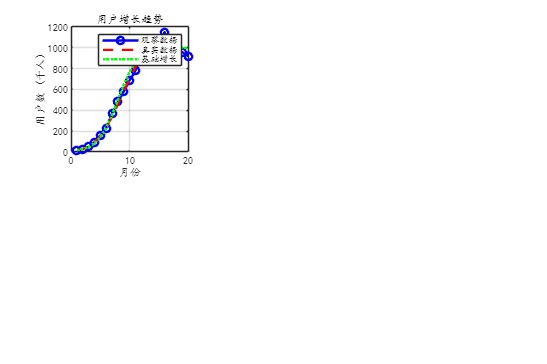

%% 2. 数据探索性分析
figure('Position', [100, 100, 1200, 800]);

% 用户增长趋势
subplot(2, 3, 1);
plot(months, observed_users/1000, 'o-', 'Color', 'b', 'LineWidth', 2, 'MarkerSize', 6);
hold on;
plot(months, true_users/1000, '--', 'Color', 'r', 'LineWidth', 2);
plot(months, base_users/1000, ':', 'Color', 'g', 'LineWidth', 2);
xlabel('月份');
ylabel('用户数 (千人)');
title('用户增长趋势');
legend('观察数据', '真实数据', '基础增长');
grid on;

alpha(0.3);

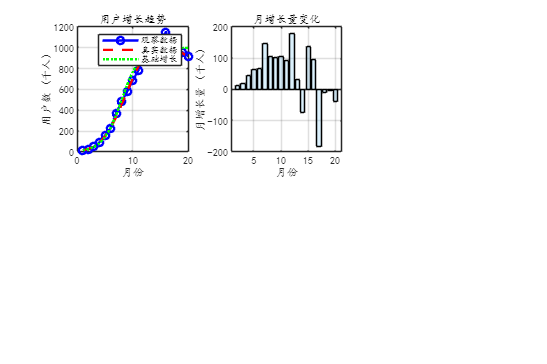

% 月增长量变化
subplot(2, 3, 2);
bar(months(2:end), monthly_growth(2:end)/1000, 'FaceColor', [0.53 0.81 0.98], 'EdgeColor', 'k');
xlabel('月份');
ylabel('月增长量 (千人)');
title('月增长量变化');
grid on;
alpha(0.3);

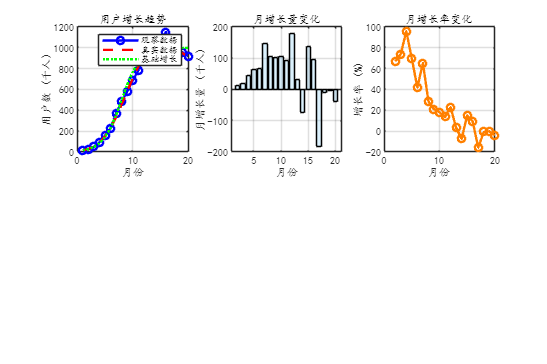

% 增长率变化
subplot(2, 3, 3);
plot(months(2:end), growth_rate(2:end), 'o-', 'Color', [1 0.5 0], 'LineWidth', 2, 'MarkerSize', 6);
xlabel('月份');
ylabel('增长率 (%)');
title('月增长率变化');
grid on;

alpha(0.3);

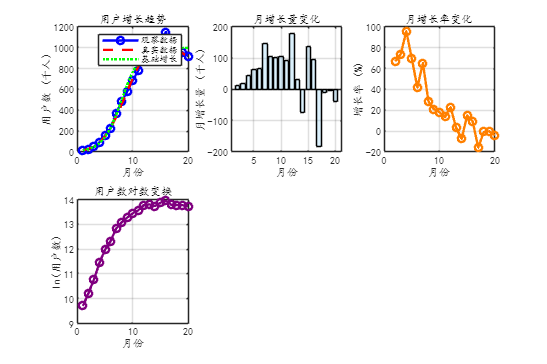

% 用户数的对数变换
subplot(2, 3, 4);
plot(months, log(observed_users), 'o-', 'Color', [0.5 0 0.5], 'LineWidth', 2, 'MarkerSize', 6);
xlabel('月份');
ylabel('ln(用户数)');
title('用户数对数变换');
grid on;

alpha(0.3);

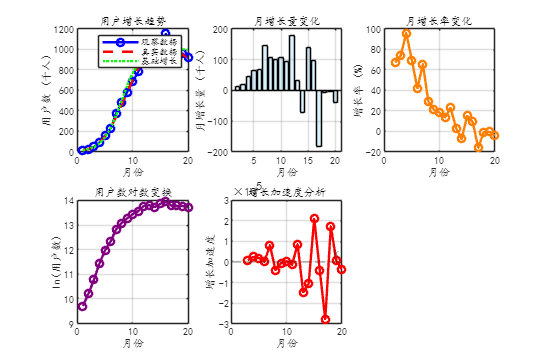

% 增长加速度（二阶导数）
growth_acceleration = diff(monthly_growth(2:end));
subplot(2, 3, 5);
plot(months(3:end), growth_acceleration, 'o-', 'Color', 'r', 'LineWidth', 2, 'MarkerSize', 6);
hold on;
yline(0, '--', 'k', 'LineWidth', 1, 'Alpha', 0.5);
xlabel('月份');
ylabel('增长加速度');
title('增长加速度分析');
grid on;

alpha(0.3);

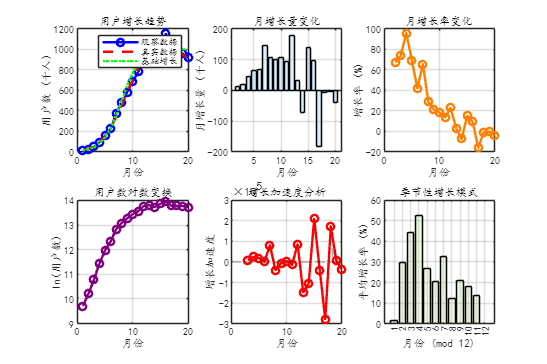

% 季节性分析
monthly_avg = zeros(1, 12);
for i = 1:12
    idx = find(mod(months, 12) == i);
    if ~isempty(idx)
        monthly_avg(i) = mean(growth_rate(idx));
    end
end
subplot(2, 3, 6);
bar(1:12, monthly_avg, 'FaceColor', [0.75 0.9 0.6], 'EdgeColor', 'k');
xlabel('月份 (mod 12)');
ylabel('平均增长率 (%)');
title('季节性增长模式');
grid on;
alpha(0.3);

%% 3. 定义多种非线性模型
% 标准Logistic增长模型
logistic_growth = @(params, x) params(1) ./ (1 + exp(-params(2) * (x - params(3))));

% 修正的Logistic模型
modified_logistic = @(params, x) params(4) + (params(1) - params(4)) ./ (1 + exp(-params(2) * (x - params(3))));

% Gompertz增长模型
gompertz_growth = @(params, x) params(1) * exp(-exp(-params(2) * (x - params(3))));

%% 4. 模型拟合与比较
disp('\n 多模型拟合比较');

\n 多模型拟合比较


disp('--------------------------------------------------');

--------------------------------------------------



models = struct();
models(1).name = 'Logistic';
models(1).func = logistic_growth;
models(1).initial = [800000, 0.5, 8];
models(1).lb = [100000, 0.1, 1];
models(1).ub = [2000000, 2.0, 15];

models(2).name = 'Modified Logistic';
models(2).func = modified_logistic;
models(2).initial = [800000, 0.5, 8, 10000];
models(2).lb = [100000, 0.1, 1, 0];
models(2).ub = [2000000, 2.0, 15, 100000];

models(3).name = 'Gompertz';
models(3).func = gompertz_growth;
models(3).initial = [800000, 0.5, 8];
models(3).lb = [100000, 0.1, 1];
models(3).ub = [2000000, 2.0, 15];

% 存储拟合结果
results = struct();
predictions = struct();

for i = 1:length(models)
    model = models(i);
    fprintf('\n拟合 %s 模型:\n', model.name);
    
    try
        % 参数拟合
        options = optimoptions('lsqcurvefit', ...
            'MaxFunctionEvaluations', 10000, ...
            'Display', 'off');
        [popt, resnorm] = lsqcurvefit(model.func, model.initial, months, observed_users, ...
            model.lb, model.ub, options);
        
        % 预测
        y_pred = model.func(popt, months);
        
        % 计算评估指标
        r2 = 1 - sum((observed_users - y_pred).^2) / sum((observed_users - mean(observed_users)).^2);
        rmse = sqrt(mean((observed_users - y_pred).^2));
        mae = mean(abs(observed_users - y_pred));
        
        % 计算AIC和BIC
        n = length(observed_users);
        k = length(popt);
        mse = mean((observed_users - y_pred).^2);
        aic = n * log(mse) + 2 * k;
        bic = n * log(mse) + k * log(n);
        
        % 存储结果
        results(i).name = model.name;
        results(i).params = popt;
        results(i).r2 = r2;
        results(i).rmse = rmse;
        results(i).mae = mae;
        results(i).aic = aic;
        results(i).bic = bic;
        
        predictions(i).name = model.name;
        predictions(i).y_pred = y_pred;
        
        fprintf('  参数: '); disp(popt');
        fprintf('  R²: %.4f\n', r2);
        fprintf('  RMSE: %.1fK\n', rmse/1000);
        fprintf('  MAE: %.1fK\n', mae/1000);
        fprintf('  AIC: %.1f\n', aic);
        fprintf('  BIC: %.1f\n', bic);
        
    catch e
        fprintf('  拟合失败: %s\n', e.message);
        continue;
    end
end


拟合 Logistic 模型:


  参数:    1.0e+06 *

    1.0091
    0.0000
    0.0000



  R²: 0.9811


  RMSE: 53.6K


  MAE: 39.6K


  AIC: 441.6


  BIC: 444.6



拟合 Modified Logistic 模型:


  参数:    1.0e+06 *

    1.0087
    0.0000
    0.0000
    0.0035



  R²: 0.9811


  RMSE: 53.6K


  MAE: 39.9K


  AIC: 443.6


  BIC: 447.6



拟合 Gompertz 模型:


  参数:    1.0e+06 *

    1.0312
    0.0000
    0.0000



  R²: 0.9756


  RMSE: 61.0K


  MAE: 49.7K


  AIC: 446.7


  BIC: 449.7


%% 5. 模型选择与比较
disp('\n 模型比较总结');

\n 模型比较总结


disp('--------------------------------------------------');

--------------------------------------------------



% 创建比较表
model_names = {results.name};
comparison_data = zeros(5, length(results));

for i = 1:length(results)
    comparison_data(1, i) = results(i).r2;
    comparison_data(2, i) = results(i).rmse / 1000;
    comparison_data(3, i) = results(i).mae / 1000;
    comparison_data(4, i) = results(i).aic;
    comparison_data(5, i) = results(i).bic;
end

disp('模型性能比较:');

模型性能比较:


comparison_table = array2table(round(comparison_data, 4), ...
    'RowNames', {'R²', 'RMSE(K)', 'MAE(K)', 'AIC', 'BIC'}, ...
    'VariableNames', model_names);
disp(comparison_table);

               Logistic    Modified Logistic    Gompertz
               ________    _________________    ________

    R²          0.9811          0.9811           0.9756 
    RMSE(K)     53.646          53.636           60.988 
    MAE(K)      39.648          39.916           49.723 
    AIC         441.61           443.6           446.74 
    BIC         444.59          447.58           449.72 




% 找出最佳模型（基于BIC）
[~, best_idx] = min([results.bic]);
best_model = results(best_idx).name;
fprintf('\n最佳模型（基于BIC）: %s\n', best_model);


最佳模型（基于BIC）: Logistic



%% 6. 最佳模型的详细分析
fprintf('\n %s 模型详细分析\n', best_model);


 Logistic 模型详细分析


disp('--------------------------------------------------');

--------------------------------------------------



best_params = results(best_idx).params;

if strcmp(best_model, 'Logistic')
    fprintf('最大用户数 (L): %.1fK\n', best_params(1)/1000);
    fprintf('增长率 (k): %.4f\n', best_params(2));
    fprintf('拐点位置 (x0): %.2f\n', best_params(3));
elseif strcmp(best_model, 'Modified Logistic')
    fprintf('最大用户数 (L): %.1fK\n', best_params(1)/1000);
    fprintf('增长率 (k): %.4f\n', best_params(2));
    fprintf('拐点位置 (x0): %.2f\n', best_params(3));
    fprintf('基础用户数 (c): %.1fK\n', best_params(4)/1000);
elseif strcmp(best_model, 'Gompertz')
    fprintf('最大用户数 (L): %.1fK\n', best_params(1)/1000);
    fprintf('增长率 (k): %.4f\n', best_params(2));
    fprintf('拐点位置 (x0): %.2f\n', best_params(3));
end

最大用户数 (L): 1009.1K


增长率 (k): 0.5449


拐点位置 (x0): 8.25


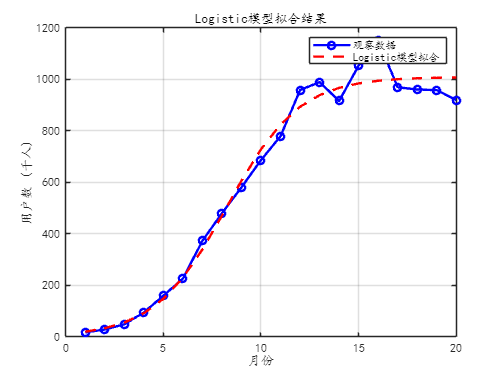

% 绘制最佳模型拟合结果
figure;
plot(months, observed_users/1000, 'o-', 'Color', 'b', 'LineWidth', 2, 'MarkerSize', 6, 'DisplayName', '观察数据');
hold on;
plot(months, predictions(best_idx).y_pred/1000, '--', 'Color', 'r', 'LineWidth', 2, 'DisplayName', [best_model '模型拟合']);
xlabel('月份');
ylabel('用户数 (千人)');
title([best_model '模型拟合结果']);
legend();
grid on;

alpha(0.3);